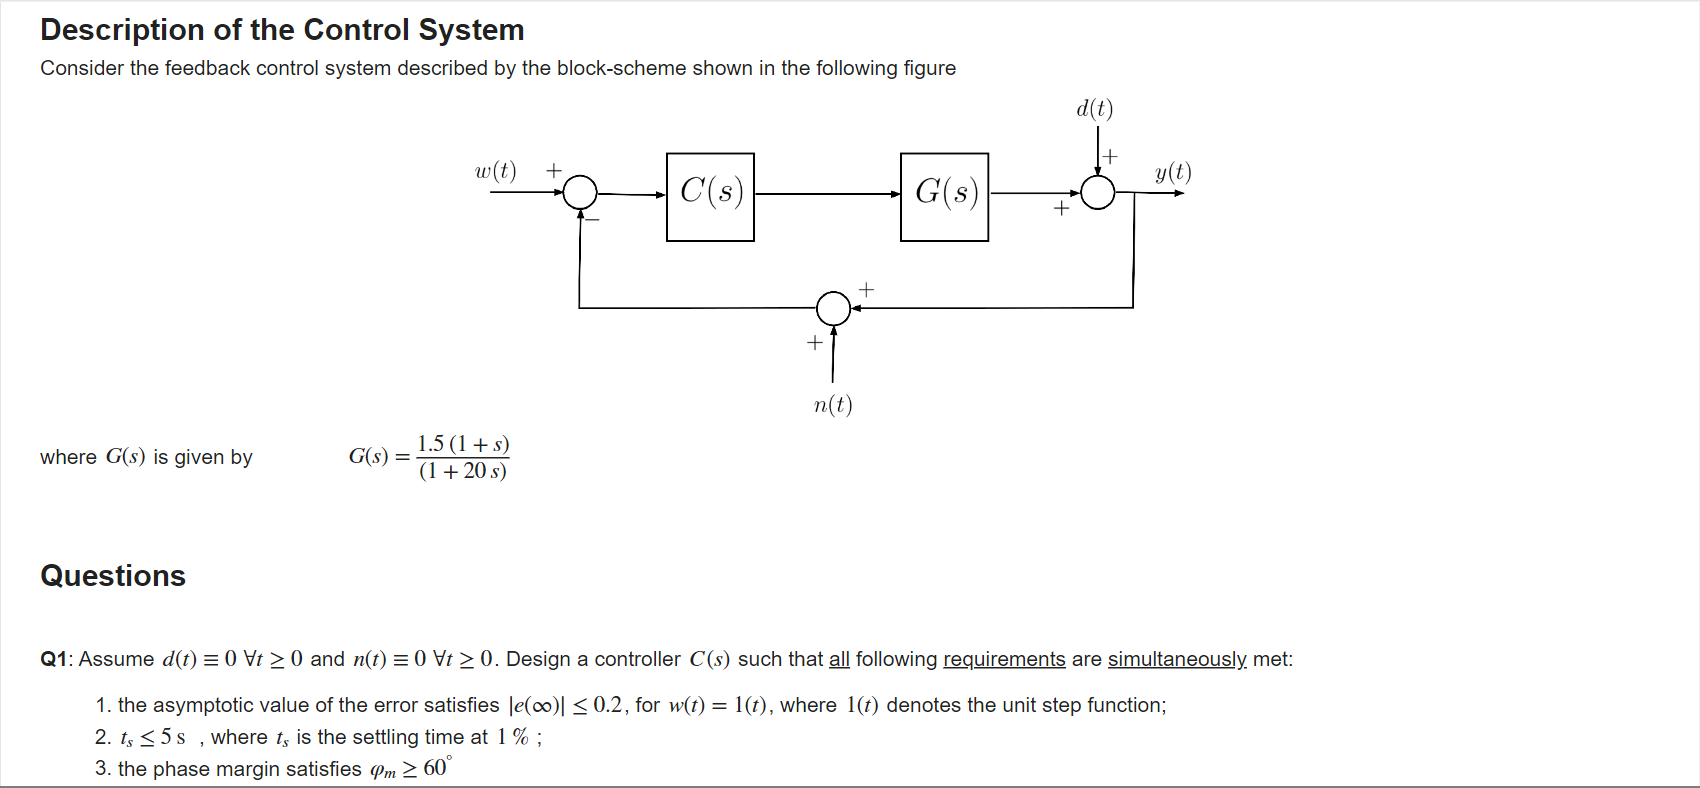

**ANALISI PRELIMINARE**

Il solo processo descritto dalla funzione di trasferimento G(s) porta ad un sistema con caratteristiche:

- margine di fase $\varphi_{m}=135\degree$

- pulsazione critica $\omega_c=0.0561$ rad/s

- sistema di tipo 0

Ovviamente non soddisfa le specifiche. 

Progettiamo un regolatore della forma $C(s) = C_1(s) C_2(s)$ dove $C_1(s)$ è progettato per soddisfare la prima specifica (comportamento statico) e $C_2(s)$ è progettato per soddisfare la seconda e terza specifica (comportamento dinamico).

**PROGETTO STATICO**

Per soddisfare il primo requisito (Q1.1), la funzione di trasferimento $L(s)$ deve essere di tipo $g \ge 0$. Scegliamo g=0 per tenere il controllore più semplice possibile.

Assumendo 

$C(s) = C_1(s) C_2(s)$  con  $C_1(s)= \mu_c$ , $C_2(0)=1$

Per soddisfare il requisito, calcoliamo

$|e(\infty)| = \frac{1}{1+\mu_L} \le 0.2$  con  $\mu_L=L(0)$ , $L(s) = C(s) G(s)$

Svolgendo alcuni passaggi, otteniamo 


$$1 + \mu_L \ge 5 \Longrightarrow \mu_L \ge 4$$
 

Considerando che $L(0) = G(0) C(0)$ abbiamo


$$\frac{3}{2}\mu_c \ge 4 \Longrightarrow \mu_c \ge \frac{8}{3}$$


**PROGETTO DINAMICO**

Possiamo procedere per cancellazione dinamica del processo, in particolare imponiamo $C_2(s) = \frac{1+20s}{s(1+s)$

In questo modo, otteniamo un regolatore che porta ad avere una FdT pari a:

$C(s) = C_1(s) C_2(s) \Longrightarrow L(s) = G(s) C(s) = \frac{\mu_c}{s}$   con $\mu_c \ge \frac{8}{3}$

A questo punto, è facile verificare che la FdT $L(s)$ soddisfa tutte le specifiche, pur di scegliere un opportuno valore di $\mu_c$ , infatti

- poichè $L(s)$ possiede un polo in $s=0$, soddisfa certamente la specifica sull'errore a regime alla risposta allo scalino unitario (Q1.1)

- la FdT garantisce di avere sempre margine di fase pari a $\varphi_m = 90\degree $, quindi anche la specifica sul margine di fase è rispettata (Q1.3)

Come possiamo vedere dai Diagrammi di Bode della funzione di trasferimento $L(s)$, il margine di fase sarà sempre pari a 90°

s=tf('s');

Gs = 1.5*(1+s)/(1+20*s); % the process TF

muC1_min = 8/3; % the minimum P gain
C1s_min = tf(muC1_min); % a pure P gain


C2s = (1+20*s)/(s*  (1+s));
Cs = C1s_min * C2s;

Ls = Cs * Gs;

omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

drawBodediagrams(Gs, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);
drawBodediagrams(Cs, omVALS, Bcolors(2, :), 2.5, '-', ...
                       Bcolors(5, :), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf);

legend(hax1,  'asympt. G(s)', 'actual G(s)', ...
             'asympt. C(s)', 'actual C(s)', ...
             'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

legend(hax2,   'asympt. G(s)', 'actual G(s)', ...
             'asympt. C(s)', 'actual C(s)', ...
             'asympt. L(s)', 'actual L(s)', ...
             'Location', 'best');

Dunque, ci resta solamente da soddisfare il requisito Q1.2.

La specifica del tempo di assestamento, risulta in un vincolo nella pulsazione $\omega_c$ e di conseguenza nella costante di guadagno $\mu_c$

Il requisito Q1.2 richiede che 

 $t_s = \frac{4.6}{\omega_c} \le 5 s \Longrightarrow \omega_c \ge 0.92$ rad/s

Sappiamo che


$$|L(j\omega_c)|= \frac{|1.5\mu_c|}{|j\omega_c|} = 1 \Longrightarrow \mu_c = \frac{2}{3}\omega_c$$


Inoltre, scegliendo $\omega_c = 12$ rad/s otteniamo $\mu_c = 8$

Ovviamente, rispettando il primo requisito che imponeva $\mu_c \ge \frac{8}{3}$

In conclusione, il controllore che rispetta tutti i requisiti risulta


$$C(s) = C_1(s) C_2(s) = \frac{8(1+20s)}{s(1+s)}$$


Non ci resta che riportare le due funzioni $G(s)$ e $C(s)$ nel **Control System Design App** per verificare i risultati ottenuti

% Defining the G(s) function

s=tf('s')
Gs=(1.5*(1+s))/(1+20*s)

% Define the controller function C(s) that meets all the requirments

Cs=(8*(1+20*s))/(s*(1+s))

% Verify the result on the Control System Design App

controlSystemDesigner(Gs,Cs)